# ASEN 3128 Homework 5

#### Ryan Hughes, Ponder Stine, William Watkins

## Problem 1

### Set up the Workspace

close all;
clear all;
clc;

### Declare Constants

global g I_x I_y I_z m R G_body g_body fb L_BE L_EB

g = 9.81; % [m/s^2], acceleration of gravity
m = 0.068; % [kg], mass of the quadcopter
R = 0.060; % [m], distance from CG to motors
I_x = 5.8 * 10 ^ (-5); % [kg*m^2], moment of inertia about x-axis
I_y = 7.2 * 10 ^ (-5); % [kg*m^2], moment of inertia about y-axis
I_z = 1.0 * 10 ^ (-4); % [kg*m^2], moment of inertia about z-axis
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
p = 0;
q = 0;
r = 0;
phi = 0;
theta = 0;
psi = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];
tSpan = 0:0.01:10;

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLinControl', tSpan, initialState);

### Plotting the results

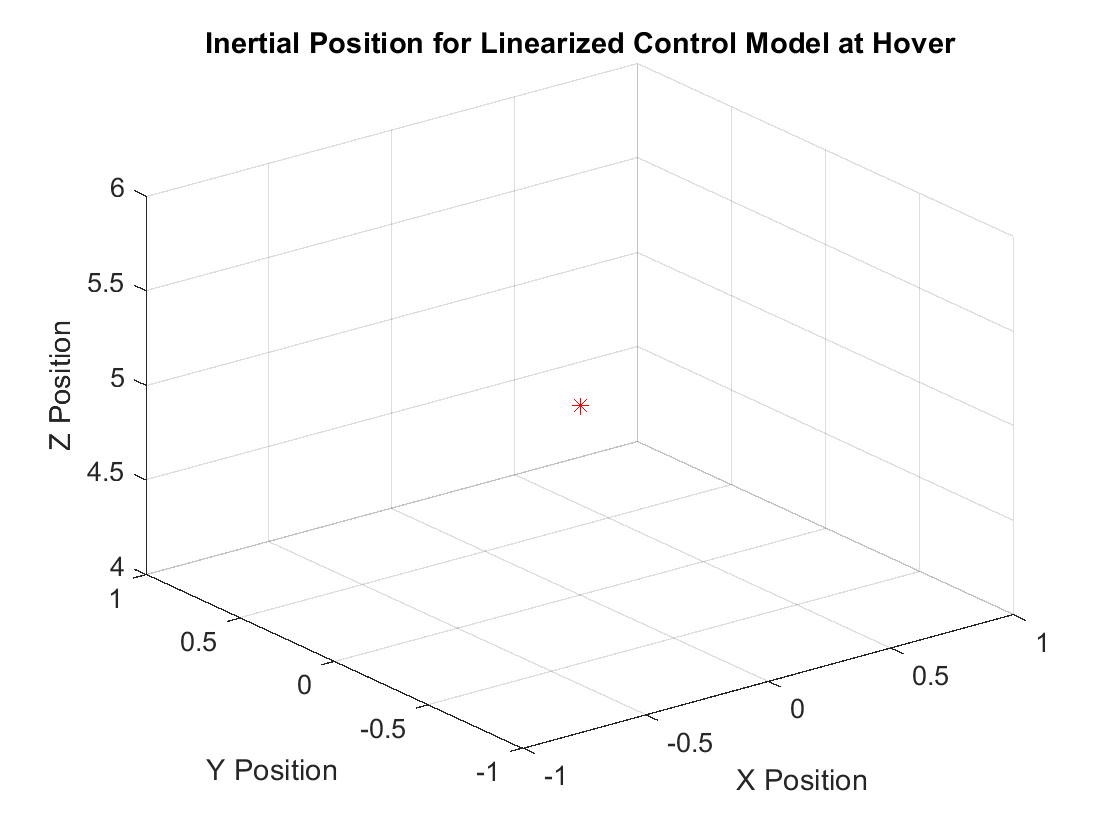

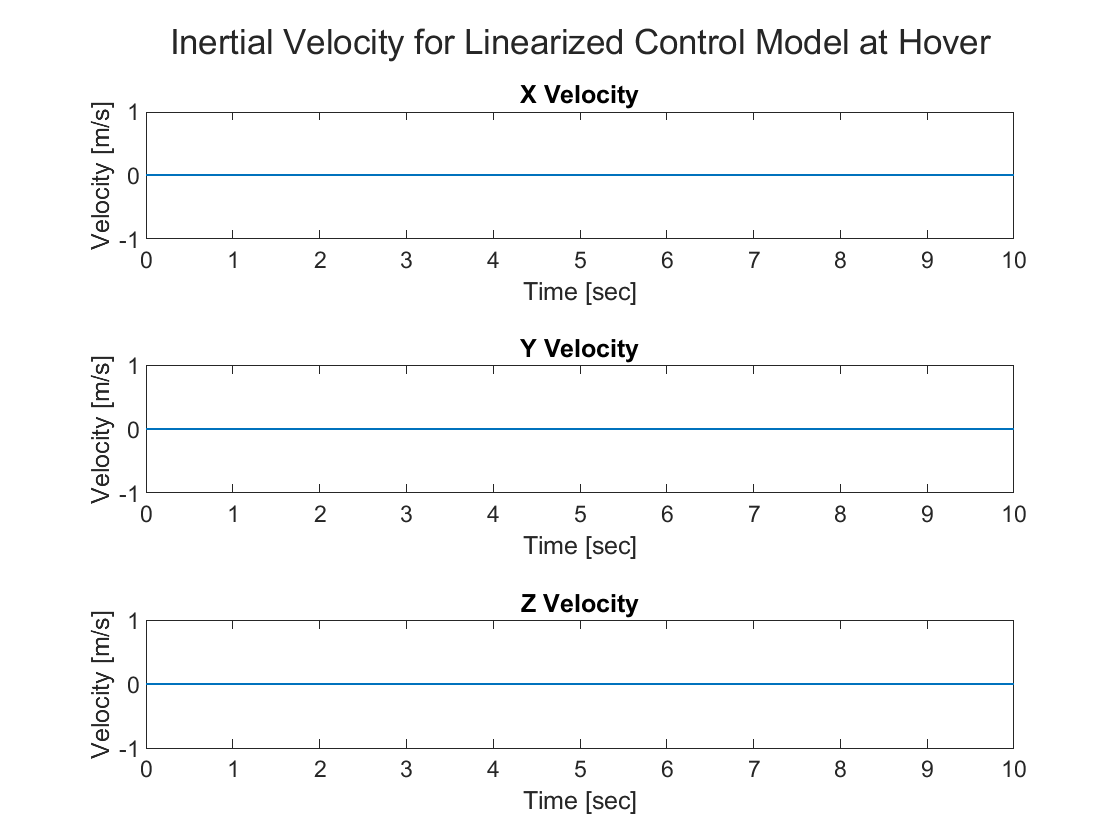

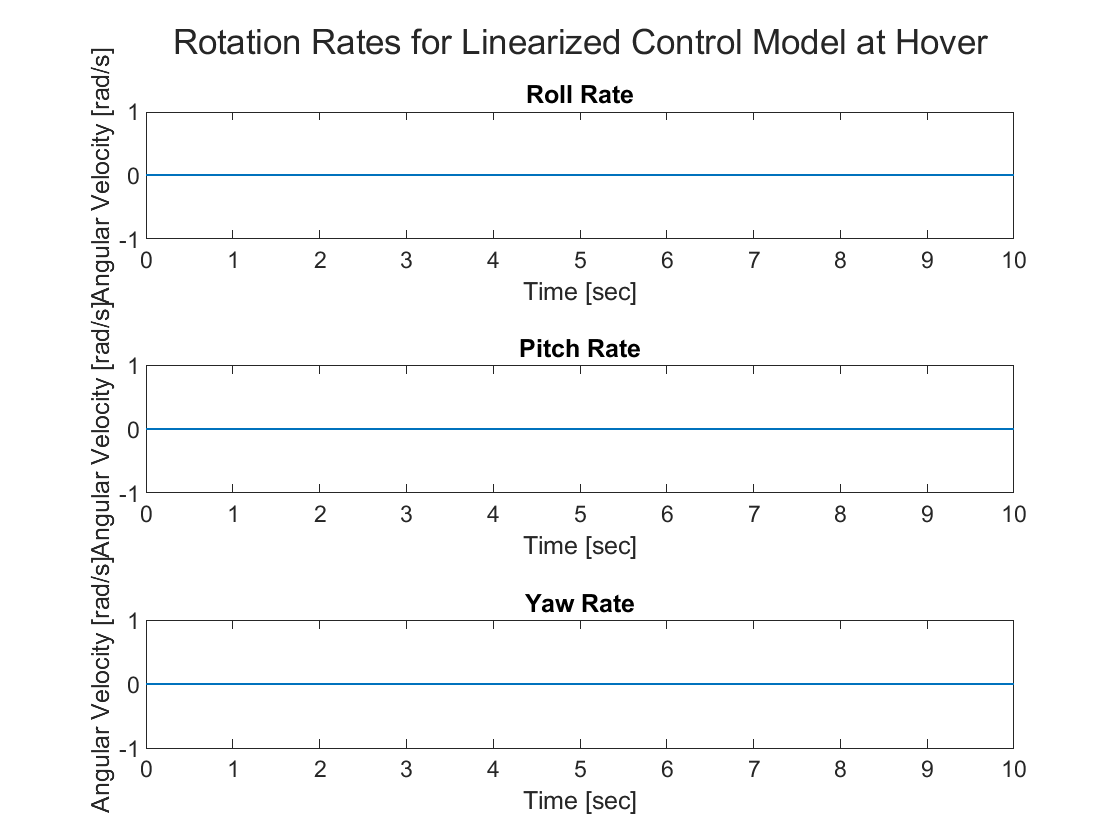

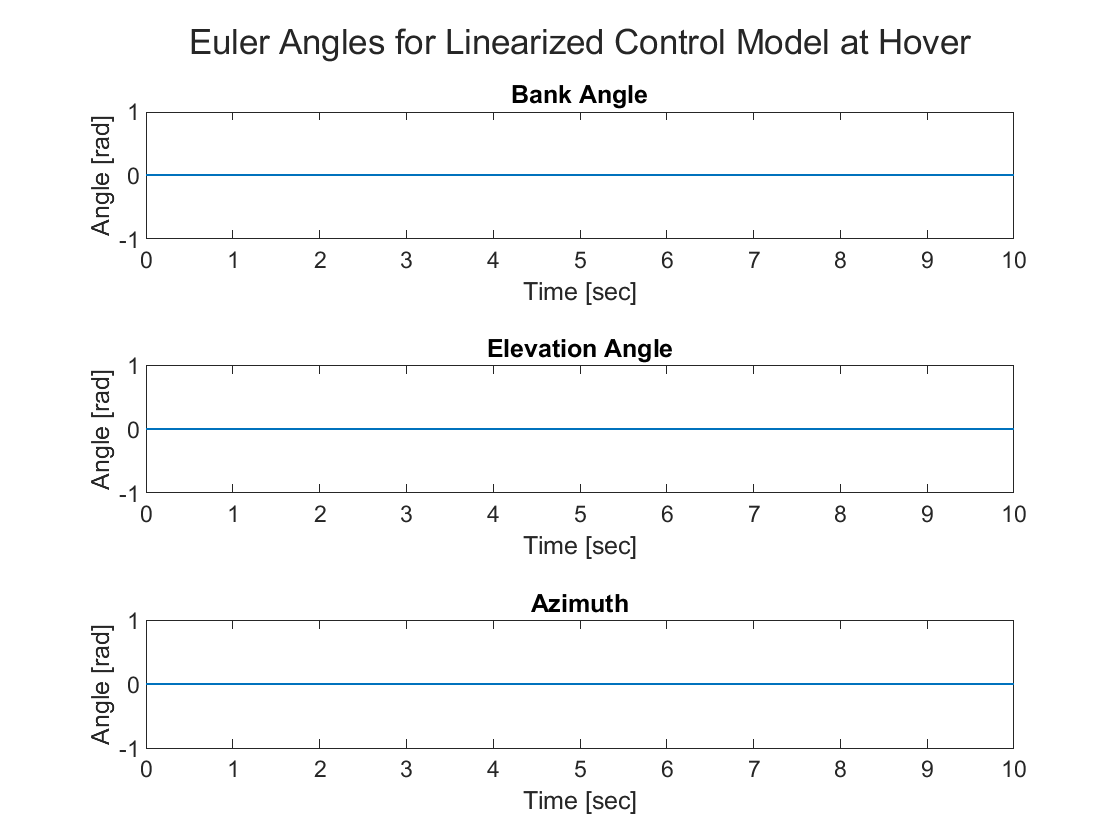

plutter(t,y,'Linearized Control Model at Hover')

## Problem 2

[tmove, ymove] = ode45('quadcopterSimulationLinOpenLoop', [tSpan 10.01:.01:20], initialState);

### Plotting the Results

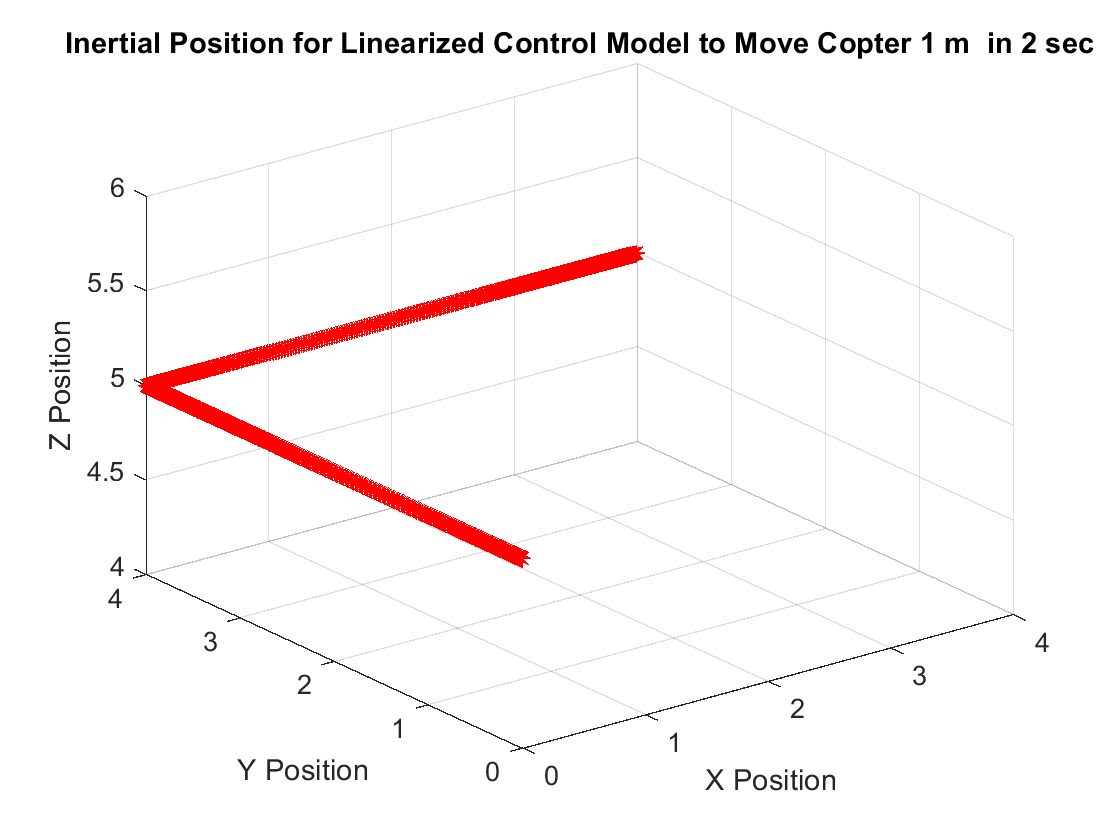

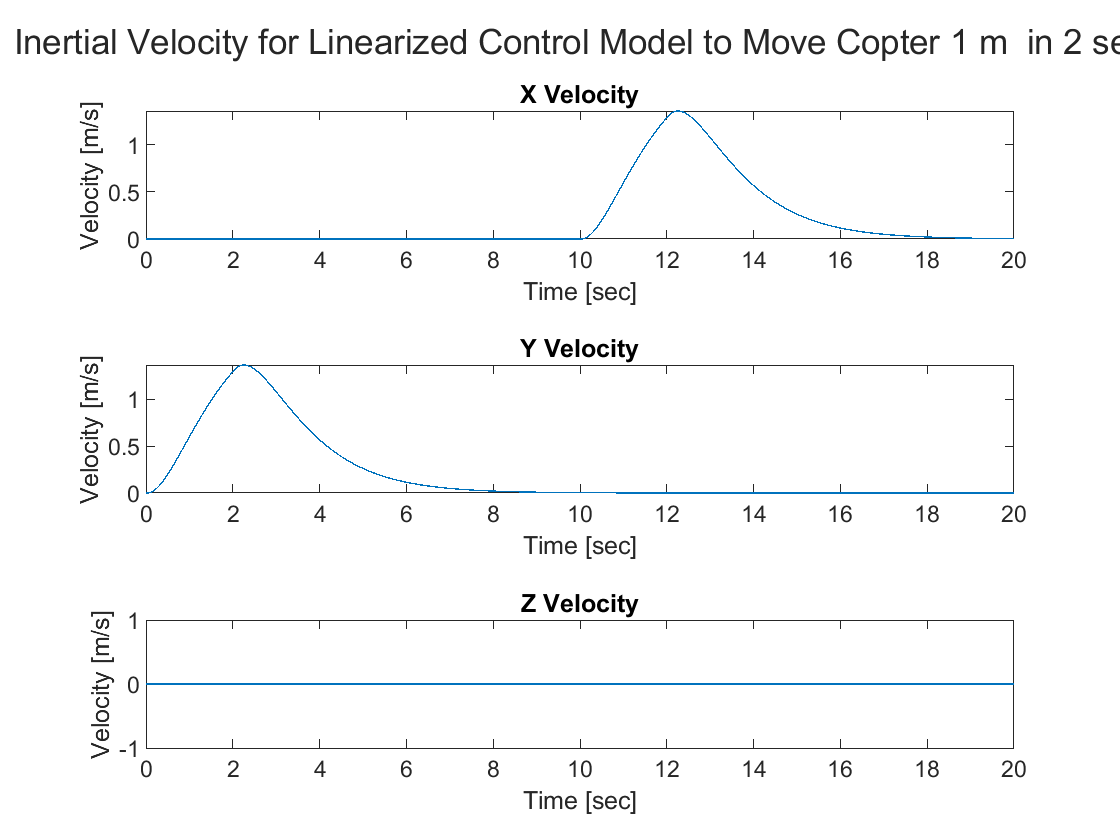

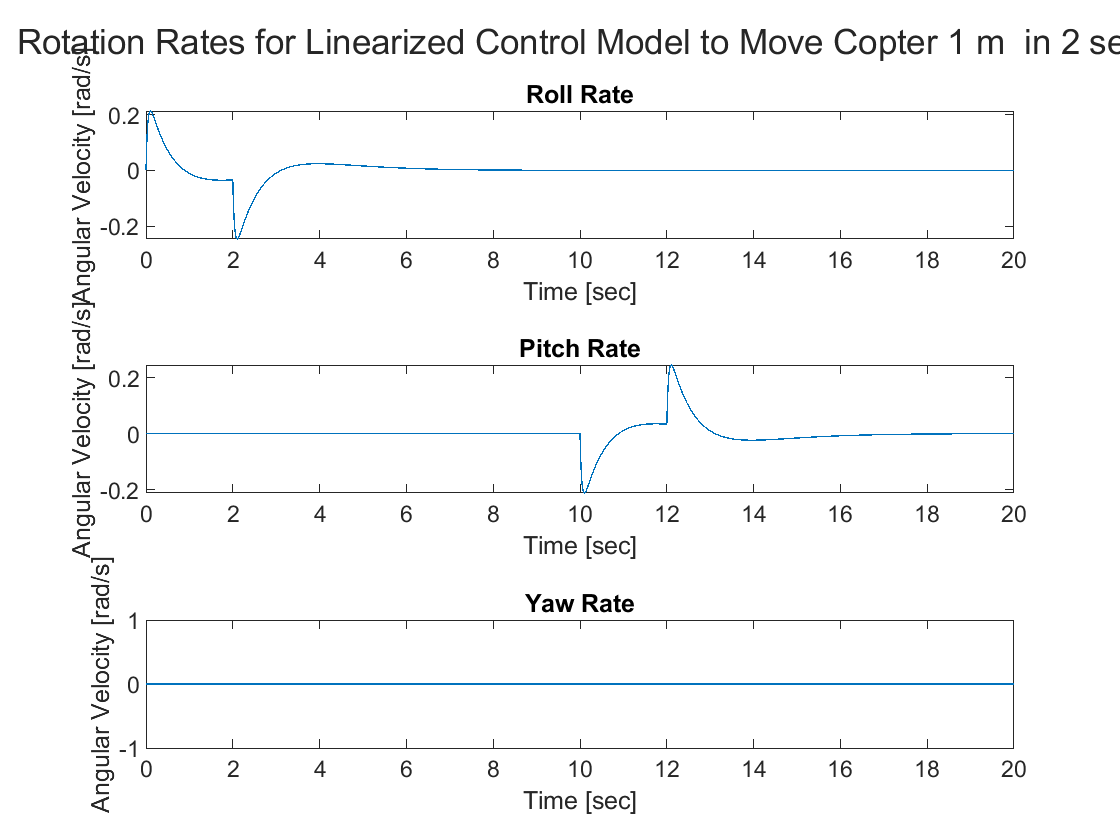

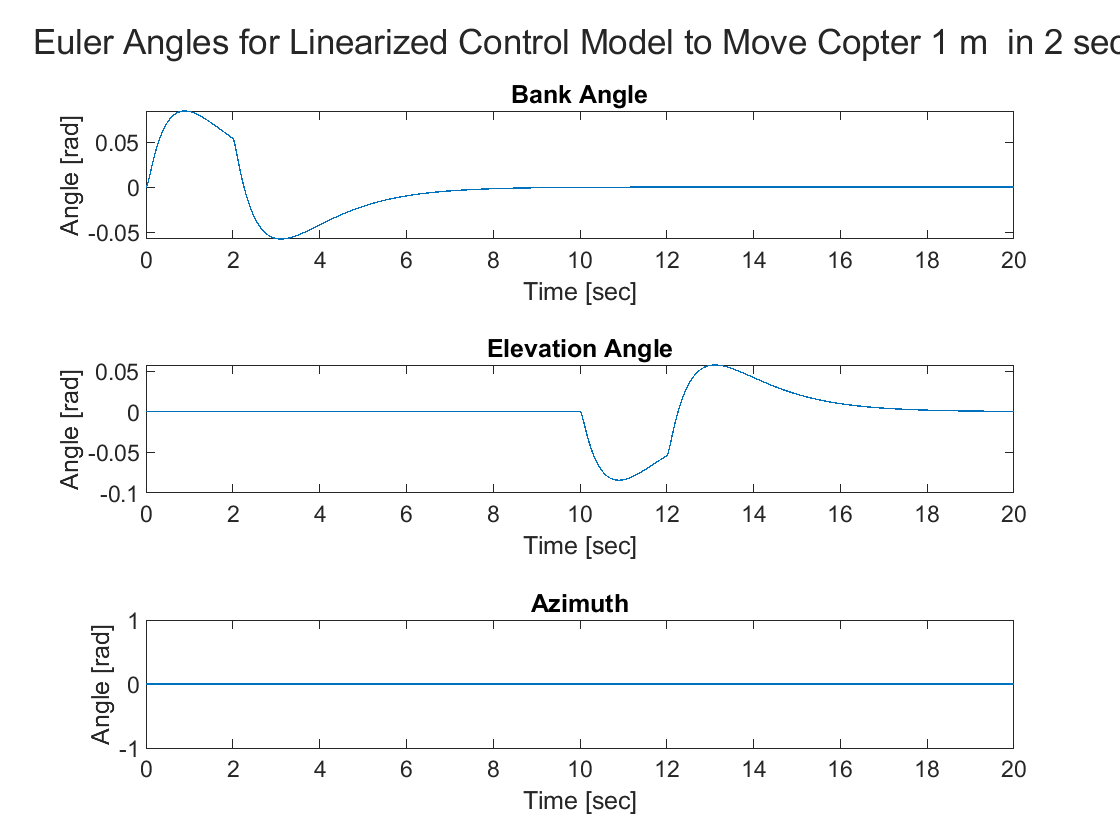

plutter(tmove, ymove, 'Linearized Control Model to Move Copter 1 m  in 2 sec');

y1 = find(ymove(:,2) > 1, 1);
fprintf('The copter reaches 1 meter in the +y-direction at t = %4.2f seconds.', tmove(y1));

The copter reaches 1 meter in the +y-direction at t = 1.84 seconds.

The copter stops moving in the +y direction when t = 2 seconds, and starts moving in the +x direction at t = 10 seconds.

x1 = find(ymove(:,1) > 1, 1);
fprintf('The copter reaches 1 meter in the +x-direction at t = %4.2f seconds.', tmove(x1));

The copter reaches 1 meter in the +x-direction at t = 11.85 seconds.

## Problem 3

Comparing the Mambo copter to the simulation.